Definindo Constantes

clear all
m = 188.6 ; % Massa do ROV
I_z = 40.50 ; %Momento de inércia ao redor Z

m_u = 450.87; %Massa virtual na direção X
m_v = 558.92; %Massa virtual na direção Y
I_r = 239.44; %Momento virtual ao redor de Z

Coeficiente de arrasto hidrodinâmicos

K_u = 82.30;
K_uu = 309.70;
K_v = 8.50;
K_vv = 505.45;
K_r = 18.21;
K_rr = 94.72;

Velocidades de equilíbrio

U = 0.5;
V = 0.5;
R = 0.126;

Construções das matrizes linearizadas

A = [ -(K_u/m_u)-((2*abs(U)*K_uu)/m_u), ((abs(R)*m_v)/m_u), 0, ((abs(V)*m_v)/m_u);
    -((abs(R)*m_u)/m_v), -(K_v/m_v)-((2*abs(V)*K_vv)/m_v), 0, -((abs(U)*m_u)/m_v);
    0, 0, 0, 1; 
    ((m_u-m_v)*abs(V)/I_r), ((m_u-m_v)*abs(U)/I_r), 0, -(K_r/I_r)-((2*abs(R)*K_rr)/I_r)];


B = [1/m_u, 0, 0;
     0, 1/m_v, 0;
     0, 0, 1/I_r;
     0, 0, 0];


C = eye(4,4);

D = zeros(4,3);

Criação do espaço de estados

sl = ss(A, B, C, D);

Determinando a função de transferência

[h1,y] = ss2tf(A, B, C, D, 1);

y1 = [y(1,1), y(1,2), y(1,3), y(1,4), 0];

tf11 = tf([h1(1,1), h1(1,2), h1(1,3), h1(1,4), h1(1,5)], y1);
tf12 = tf([h1(2,1), h1(2,2), h1(2,3), h1(2,4), h1(2,5)], y1);
tf13 = tf([h1(3,1), h1(3,2), h1(3,3), h1(3,4), h1(3,5)], y1);
tf14 = tf([h1(4,1), h1(4,2), h1(4,3), h1(4,4), h1(4,5)], y1);

[h2] = ss2tf(A, B, C, D, 2);

tf21 = tf([h2(1,1), h2(1,2), h2(1,3), h2(1,4), h2(1,5)], y1);
tf22 = tf([h2(2,1), h2(2,2), h2(2,3), h2(2,4), h2(2,5)], y1);
tf23 = tf([h2(3,1), h2(3,2), h2(3,3), h2(3,4), h2(3,5)], y1);
tf24 = tf([h2(4,1), h2(4,2), h2(4,3), h2(4,4), h2(4,5)], y1);


[h3] = ss2tf(A, B, C, D, 3);

tf31 = tf([h3(1,1), h3(1,2), h3(1,3), h3(1,4), h3(1,5)], y1);
tf32 = tf([h3(2,1), h3(2,2), h3(2,3), h3(2,4), h3(2,5)], y1);
tf33 = tf([h3(3,1), h3(3,2), h3(3,3), h3(3,4), h3(3,5)], y1);
tf34 = tf([h3(4,1), h3(4,2), h3(4,3), h3(4,4), h3(4,5)], y1);


Plotando os polos do sistema

pz = pzmap(sl);
grid on

Vetor de tempo

t = 0:0.01:60;
dt = 0.1;

Determinando as entradas

u1 = zeros(size(t));
u2 = zeros(size(t));
u3 = zeros(size(t));

for i = 1:1:500
    u1(i) = 0;
end

for i = 501:1:6001
    u1(i) = 10;
end

for i = 1:1:6001
    u2(i) = 5*sin(2*pi()*0.1*t(i));
end

u = [u1;u2;u3];

n = length(t);
x = zeros(4,n);

for j = 1:1:n-1
    x(:,j+1) = expm(A*dt)*x(:,j) + expm(A*dt)*B*u(:,j)*dt;
end
x1 = U + x(1,:);
x2 = V + x(2,:);
x4 = R + x(4,:);

Simulação utilizando a FT

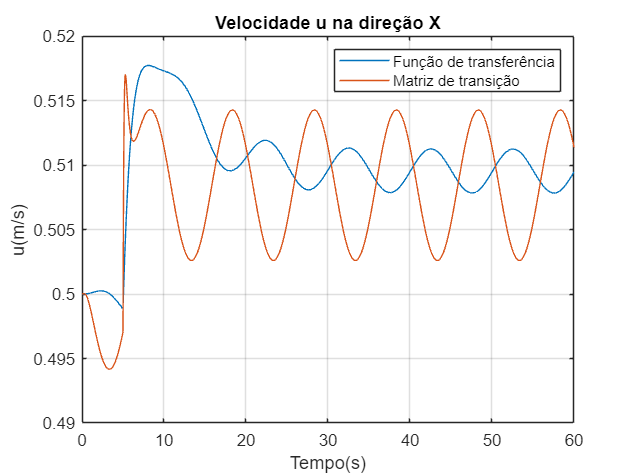

y11 = lsim(u1, t, tf11);
y12 = lsim(u2, t, tf21);
y13 = lsim(u3, t, tf31);

y1 =  U +y11 + y12 + y13;


y21 = lsim(u1, t, tf12);
y22 = lsim(u2, t, tf22);
y23 = lsim(u3, t, tf32);

y2 = V + y21 + y22 + y23;

y31 = lsim(u1, t, tf14);
y32 = lsim(u2, t, tf24);
y33 = lsim(u3, t, tf34);

y3 = R + y31 + y32 + y33;

plot(t, y1, t, x1)
grid on
title 'Velocidade u na direção X'
xlabel 'Tempo(s)'
ylabel 'u(m/s)'
legend('Função de transferência', 'Matriz de transição')

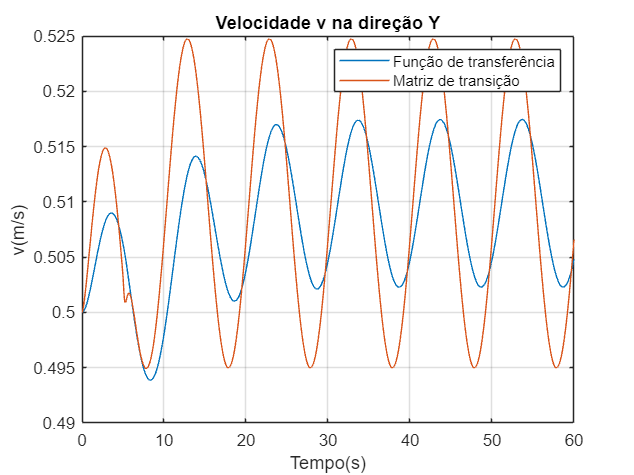


plot(t, y2, t, x2)
grid on
title 'Velocidade v na direção Y'
xlabel 'Tempo(s)'
ylabel 'v(m/s)'
legend('Função de transferência', 'Matriz de transição')

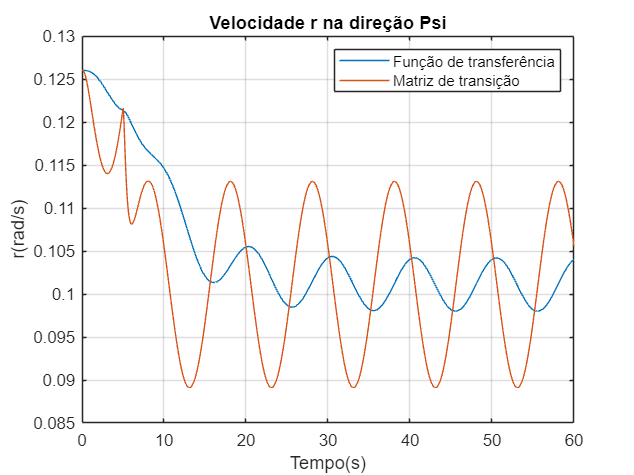


plot(t, y3, t, x4)
grid on
title 'Velocidade r na direção Psi'
xlabel 'Tempo(s)'
ylabel 'r(rad/s)'
legend('Função de transferência', 'Matriz de transição')